# Module 5, Lesson 1: Synchronizing data with timetables

This Live Script recreates the workflow shown in the video "Synchronizing data with timetables"

### Load the data

The data in `bostemp.mat` is a set of temperature readings in Celsius sampled every hour at Logan Airport for the entire month of January, 2011. The data in `officetemp.mat` is a set of temperature readings in Fahrenheit recorded inside an office building, sampled once per half hour.

load bostemp.mat tempC
tempC

tempC =    -2.2000
   -2.8000
   -2.8000
   -2.8000
   -2.8000
   -2.8000
   -2.8000
   -2.8000
   -2.2000
   -1.1000



load officetemp.mat temp
temp

temp =     75
    74
    74
    74
    74
    74
    74
    74
    75
    75


### Compare plots

Notice the Boston data has around 750 datapoints, whereas the Office data has over 5000. This means the Office data was recorded for a longer period of time, even when considering the difference in sample rate. 

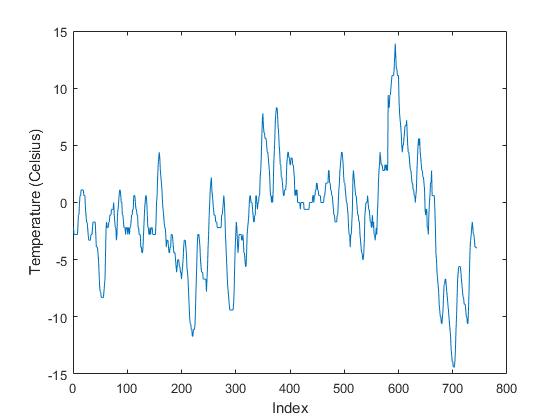

plot(tempC)
xlabel("Index")
ylabel("Temperature (Celsius)")

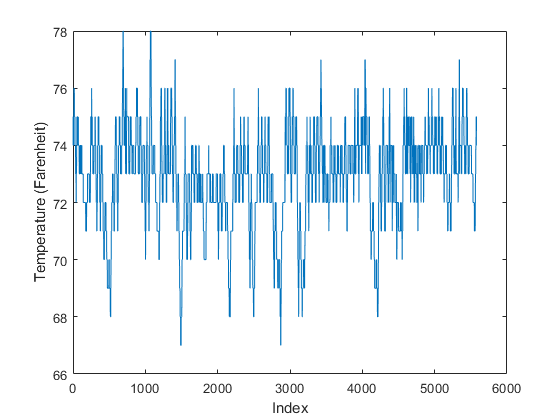


plot(temp)
xlabel("Index")
ylabel("Temperature (Farenheit)")

### Create timetables

The function `timetable()` can be used to construct timetables. If you have the sample rate in Hz, you can use this with the `'SampleRate'` option. Or you can use a `'TimeStep'` as demonstrated here.

bostonTemp = timetable(tempC,'TimeStep',hours(1))

bostonTemp = 744×1 timetable
    Time     tempC
    _____    _____

    0 hr     -2.2 
    1 hr     -2.8 
    2 hr     -2.8 
    3 hr     -2.8 
    4 hr     -2.8 
    5 hr     -2.8 
    6 hr     -2.8 
    7 hr     -2.8 
    8 hr     -2.2 
    9 hr     -1.1 
    10 hr    -1.1 
    11 hr       0 
    12 hr     0.6 
    13 hr     0.6 
    14 hr     1.1 
    15 hr     1.1 



officeTemp = timetable(temp,'TimeStep',minutes(30))

officeTemp = 5584×1 timetable
     Time      temp
    _______    ____

    0 min       75 
    30 min      74 
    60 min      74 
    90 min      74 
    120 min     74 
    150 min     74 
    180 min     74 
    210 min     74 
    240 min     75 
    270 min     75 
    300 min     75 
    330 min     76 
    360 min     76 
    390 min     76 
    420 min     75 
    450 min     75 


### Demonstrate other constructions

Since both timetables start at a time of 0, it's implied these signals started at the same time. This may not always be the case. For example, say you have a datetime array of exact times for the Boston data.

% There are 31*24 = 744 hours in January, so you can make a datetime 
% array by specifying the integers 0 to 743
hoursJan = 0:743; 
exactTimes = datetime(2011,1,1,hoursJan,0,0)'

exactTimes = 1×744 datetime array
Columns 1 through 434

   01-Jan-2011 00:00:00   01-Jan-2011 01:00:00   01-Jan-2011 02:00:00   01-Jan-2011 03:00:00   01-Jan-2011 04:00:00   01-Jan-2011 05:00:00   01-Jan-2011 06:00:00   01-Jan-2011 07:00:00   01-Jan-2011 08:00:00   01-Jan-2011 09:00:00   01-Jan-2011 10:00:00   01-Jan-2011 11:00:00   01-Jan-2011 12:00:00   01-Jan-2011 13:00:00   01-Jan-2011 14:00:00   01-Jan-2011 15:00:00   01-Jan-2011 16:00:00   01-Jan-2011 17:00:00   01-Jan-2011 18:00:00   01-Jan-2011 19:00:00   01-Jan-2011 20:00:00   01-Jan-2011 21:00:00   01-Jan-2011 22:00:00   01-Jan-2011 23:00:00   02-Jan-2011 00:00:00   02-Jan-2011 01:00:00   02-Jan-2011 02:00:00   02-Jan-2011 03:00:00   02-Jan-2011 04:00:00   02-Jan-2011 05:00:00   02-Jan-2011 06:00:00   02-Jan-2011 07:00:00   02-Jan-2011 08:00:00   02-Jan-2011 09:00:00   02-Jan-2011 10:00:00   02-Jan-2011 11:00:00   02-Jan-2011 12:00:00   02-Jan-2011 13:00:00   02-Jan-2011 14:00:00   02-Jan-2011 15:00:00   02-Jan-2011 16:00:00

This datetime array can be used to construct a timetable with the `'RowTimes'` option.

bostonTemp2 = timetable(tempC,'RowTimes',exactTimes)

bostonTemp2 = 744×1 timetable
            Time            tempC
    ____________________    _____

    01-Jan-2011 00:00:00    -2.2 
    01-Jan-2011 01:00:00    -2.8 
    01-Jan-2011 02:00:00    -2.8 
    01-Jan-2011 03:00:00    -2.8 
    01-Jan-2011 04:00:00    -2.8 
    01-Jan-2011 05:00:00    -2.8 
    01-Jan-2011 06:00:00    -2.8 
    01-Jan-2011 07:00:00    -2.8 
    01-Jan-2011 08:00:00    -2.2 
    01-Jan-2011 09:00:00    -1.1 
    01-Jan-2011 10:00:00    -1.1 
    01-Jan-2011 11:00:00       0 
    01-Jan-2011 12:00:00     0.6 
    01-Jan-2011 13:00:00     0.6 
    01-Jan-2011 14:00:00     1.1 
    01-Jan-2011 15:00:00     1.1 


Or perhaps you already have the data in a table, which might be the case if you use the Import Tool. In this case, you can convert a table to a timetable with the function `table2timetable()`.

bostonTemp3 = table(exactTimes,tempC);
bostonTemp3 = table2timetable(bostonTemp3)

bostonTemp3 = 744×1 timetable
            Var1            tempC
    ____________________    _____

    01-Jan-2011 00:00:00    -2.2 
    01-Jan-2011 01:00:00    -2.8 
    01-Jan-2011 02:00:00    -2.8 
    01-Jan-2011 03:00:00    -2.8 
    01-Jan-2011 04:00:00    -2.8 
    01-Jan-2011 05:00:00    -2.8 
    01-Jan-2011 06:00:00    -2.8 
    01-Jan-2011 07:00:00    -2.8 
    01-Jan-2011 08:00:00    -2.2 
    01-Jan-2011 09:00:00    -1.1 
    01-Jan-2011 10:00:00    -1.1 
    01-Jan-2011 11:00:00       0 
    01-Jan-2011 12:00:00     0.6 
    01-Jan-2011 13:00:00     0.6 
    01-Jan-2011 14:00:00     1.1 
    01-Jan-2011 15:00:00     1.1 


### Change the units

The data type for the time columns in `bostonTemp` and `officeTemp` are duration values, meaning they have units of time like hours and minutes. You can change the units in the time column by specifying the format.

For example, to change the units of `bostonTemp` from hours to days, specify the format as the letter `'d'`.

bostonTemp.Time.Format = "d"

Now when you replot the data, you can see the total duration is 31 days.

plot(bostonTemp.Time,bostonTemp.tempC)
xlabel("Time")
ylabel("Temperature (°C)")

Note that you don't need to convert units in order to synchronize two timetables. Even though `bostonTemp` has units of days, it can still be synchronized with the `officeTemp` data that has units of minutes.

## Change the sample rate

To convert the sample rate of a time table, use the `retime()` function.

In this example, specify a linear interpolation method and a new time step of 30 minutes.

newBostonTemp = retime(bostonTemp,"regular","linear","TimeStep",minutes(30))

### Use summary statistics

Instead of an interpolation method, you can "aggregate" the data into bins and apply a summary statistic like "mean", "min", or "max". This type of operation is called "windowing" since your splitting up the signal in consecutive "windows".

In this example, you can calculate the daily high and low temperatures of the Boston data by finding the max and min values over each day.

dailyHigh = retime(bostonTemp,"regular","max","TimeStep",days(1));
dailyLow = retime(bostonTemp,"regular","min","TimeStep",days(1));

When you plot the data, you can see the number of data points decreased significantly. Now there is only two datapoints for each day: the daily high and low temperatures.

plot(dailyHigh.Time,dailyHigh.tempC,'o-')
hold on
plot(dailyLow.Time,dailyLow.tempC,'o-')
hold off
xlabel("Time")
ylabel("Temperature (°C)")
legend("Daily high","Daily low")

### Synchronize the two timetables

Now you can finally get to the synchronizing step using the `synchronize` function.

Notice the output timetable now has 3 columns

syncTemp = synchronize(bostonTemp,officeTemp,"regular","linear", ...
    "TimeStep",hours(1))

You can plot the result with a stackedplot. The two tables have been successfully synchronized, but the Boston data has been extrapolated beyond the first month, leading to the long sloped line

stackedplot(syncTemp);
title("Incorrect synchronize result")

#### Specify the "EndValues" option

To prevent this extrapolation, you can specify that a NaN value should be inserted after the end of either signal.

syncTemp = synchronize(bostonTemp,officeTemp,"regular","linear", ...
    "TimeStep",hours(1),"EndValues",NaN);

Now when you plot the result, you can see the Boston signal stops after one month

stackedplot(syncTemp);
title("Correct synchronize results")

Lastly, you can look at just the first month by specifying the limits of the x-axis.

stackedplot(syncTemp);
title("Synchronized temperatures (first month)")
xlim(days([0 31]))